# Design of a Controller for a Dynamic System with an RHP Uncertain Zero

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure   

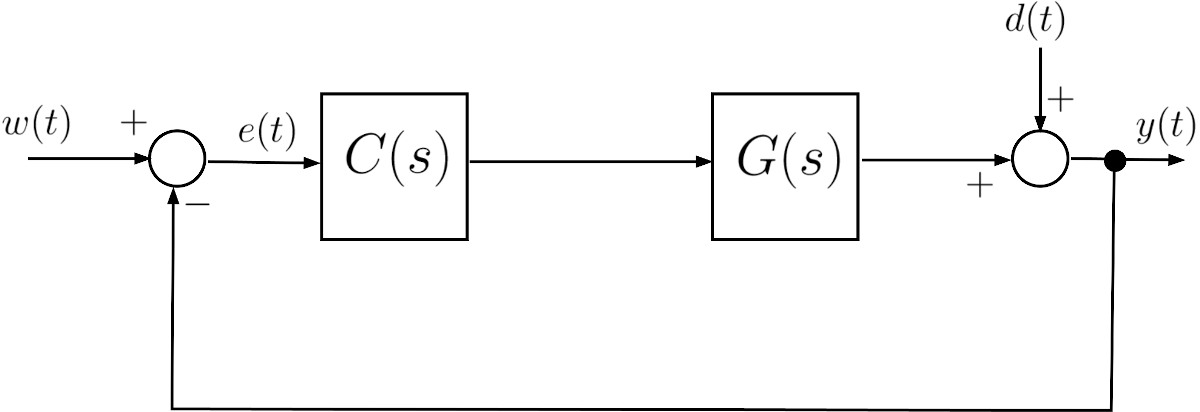	

where $G(s)$ is given by                


$$G(s) = 12\, \frac{1-T\,s}{(1+25\,s)\,(1+0.04\,s)}\,,\quad T \in \left[0.25\,,\; 0.5\right]$$
	

## **Question**		

**Q1**: Design a controller $C(s) = \mu_C \, \frac{1+\tau\,s}{s}\, ,\quad\mu_C>0,\;\tau>0$ such that all following requirements are simultaneously met: 

- The crossover frequency $\omega_c$ satisfies: $\omega_c \in \left[1\,,\; 2 \right]\;\text{rad/s}$;

- The phase margin satisfies: $\varphi_m \ge 40^{\degree}$;

- $\left| e(\infty)\right| =0$ for $w(t) = A\cdot \mathbf{1}(t)$ and $d(t) = B \cdot \mathbf{1}(t)$ $\forall A,\,B \in \mathbb{R}$, where $\mathbf{1}(t)$ denotes the unit step function.

[Excerpt from the written examination on date 2023/08/28]	

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  				

## Solution 

Let's define the transfer function of the process $G(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function.

clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

